%% Konvolúciós Kódolás és Viterbi Dekódolás Onramp (MATLAB)
% Ez a szkript bemutatja egy alapvető konvolúciós kódoló és Viterbi
% dekódoló felépítését és tesztelését egy zajos csatornán keresztül.

clear; clc; close all;

%% 1. Rendszer paraméterek definiálása
% A konvolúciós kódolót általában két paraméter határozza meg:
% a Kényszerhossz (Constraint Length) és a Generátor polinomok.

K = 7; % Kényszerhossz: A léptetőregiszter mérete. Minél nagyobb, annál jobb a hibajavítás.
% A generátor polinomok mondják meg, hogy a léptetőregiszter melyik celláit
% kapcsoljuk össze XOR kapuval a kimenet(ek) előállításához.
% Oktális formátumban szokás megadni. A [171 133] egy ipari standard (pl. WiFi).
poly = [171 133]; 

% Trellis struktúra létrehozása. Ez a "térkép", amit a Viterbi algoritmus használ.
trellis = poly2trellis(K, poly); 

numBits = 10000; % Mennyi bitet szeretnénk szimulálni
snr_dB = 4;      % Jel-Zaj viszony (Signal-to-Noise Ratio) decibelben. 
                 % Alacsonyabb érték = nagyobb zaj.

fprintf('--- Konvolúciós Kódolás Szimuláció Indítása ---\n');

--- Konvolúciós Kódolás Szimuláció Indítása ---


fprintf('Generált bitek száma: %d\n', numBits);

Generált bitek száma: 10000


fprintf('Csatorna SNR: %d dB\n\n', snr_dB);

Csatorna SNR: 4 dB




%% 2. Adatok generálása
% Véletlenszerű 0 és 1 értékekből álló oszlopvektor
txData = randi([0 1], numBits, 1);

%% 3. Konvolúciós Kódolás (Adó oldal)
% A konvolúciós kódoló redundanciát ad a jelhez.
% Mivel R=1/2 a kódarányunk (2 polinomunk van), a kimenet kétszer olyan hosszú lesz.
txCodedData = convenc(txData, trellis);

fprintf('Eredeti adatméret: %d bit\n', length(txData));

Eredeti adatméret: 10000 bit


fprintf('Kódolt adatméret : %d bit (R=1/2 kódarány miatt)\n\n', length(txCodedData));

Kódolt adatméret : 20000 bit (R=1/2 kódarány miatt)




%% 4. Moduláció (BPSK)
% A biteket logikai értékekből fizikai jelekké (szimbólumokká) kell alakítani.
% BPSK: Binaris Fázisbillentyűzés. 
% 0 -> -1
% 1 -> +1
txModulated = 2*txCodedData - 1; 
% Megjegyzés: Ha kódolatlanul küldenénk, akkor az eredeti txData-t modulálnánk ugyanígy.
txModulated_uncoded = 2*txData - 1;

%% 5. Átvitel a zajos csatornán (AWGN)
% Additív Fehér Gauss-Zaj hozzáadása a jelhez.
% Kiszámítjuk a jel teljesítményét, és a kívánt SNR alapján adunk hozzá zajt.
rxSignal_coded = awgn(txModulated, snr_dB, 'measured');
rxSignal_uncoded = awgn(txModulated_uncoded, snr_dB, 'measured');

%% 6. Demoduláció
% Kódolatlan eset: Egyszerű küszöbérték-döntés (Hard Decision)
% Ha a vett jel > 0, akkor 1-nek tekintjük, különben 0.
rxDemodulated_uncoded = (rxSignal_uncoded > 0);

% Kódolt eset (Hard Decision a dekódoló számára)
% Itt is 0/1 szintre hozzuk a vételt, mielőtt a Viterbinek adjuk.
% (Létezik 'Soft Decision' is, ami még jobb, mert megtartja az amplitúdó információt,
% de a Hard Decision könnyebben érthető elsőre).
rxDemodulated_coded = (rxSignal_coded > 0);

%% 7. Viterbi Dekódolás (Vevő oldal)
% A Viterbi dekódoló a Trellis térkép alapján megkeresi a legvalószínűbb
% eredeti bitfolyamot a zajos, de kódolt bemenetből.
traceBack = 32; % Visszakövetési mélység. Általában 5 * Kényszerhossz.
% Ez határozza meg, hány állapotot tart a memóriában a döntés előtt.

rxData_decoded = vitdec(rxDemodulated_coded, trellis, traceBack, 'trunc', 'hard');

%% 8. Hibaszámítás és Eredmények Értékelése
% Összehasonlítjuk a vett (és dekódolt) biteket az eredetileg elküldöttel.

% Kódolatlan rendszer hibaaránya (Bit Error Rate - BER)
[numErrors_uncoded, ber_uncoded] = biterr(txData, rxDemodulated_uncoded);

% Kódolt (Konvolúciós + Viterbi) rendszer hibaaránya
[numErrors_coded, ber_coded] = biterr(txData, rxData_decoded);

fprintf('--- Eredmények %d dB SNR mellett ---\n', snr_dB);

--- Eredmények 4 dB SNR mellett ---


fprintf('Kódolatlan rendszer BER: %f (%d hibás bit)\n', ber_uncoded, numErrors_uncoded);

Kódolatlan rendszer BER: 0.053600 (536 hibás bit)


fprintf('KÓDOLT rendszer BER    : %f (%d hibás bit)\n\n', ber_coded, numErrors_coded);

KÓDOLT rendszer BER    : 0.005300 (53 hibás bit)




if ber_coded < ber_uncoded
    fprintf('SIKER! A konvolúciós kódolás sikeresen kijavította a hibák egy részét (vagy mindet)!\n');
else
    fprintf('A kódolás nem javított. Próbáld magasabb SNR értékkel (kevesebb zaj).\n');
end

SIKER! A konvolúciós kódolás sikeresen kijavította a hibák egy részét (vagy mindet)!


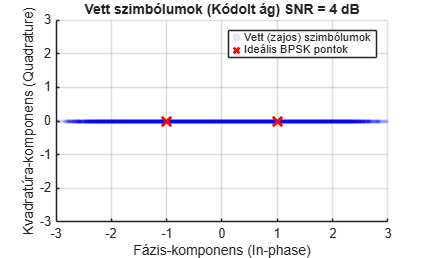


%% 9. Vizuális Ellenőrzés (Opcionális - Scatter Plot)
% Nézzük meg, hogyan néz ki a zajos jel a vevőnél!
figure('Name', 'BPSK Konstelláció Zajos Csatornán', 'NumberTitle', 'off');
scatter(real(rxSignal_coded), imag(rxSignal_coded), 10, 'b', 'filled', 'MarkerFaceAlpha', 0.1);
hold on;
% Ideális pontok pirossal
scatter([-1 1], [0 0], 100, 'r', 'x', 'LineWidth', 2);
title(sprintf('Vett szimbólumok (Kódolt ág) SNR = %d dB', snr_dB));
xlabel('Fázis-komponens (In-phase)');
ylabel('Kvadratúra-komponens (Quadrature)');
grid on;
axis([-3 3 -3 3]);
legend('Vett (zajos) szimbólumok', 'Ideális BPSK pontok');